%%  EE368 Lab0
%   Two stage op-amp Simulator
%   H = 2s(s+2) / s^2+s+1  

% Pole Zero Map
num = [2,4,0];
dem = [1 1 1];
H = tf(num,dem)

H =
 
  2 s^2 + 4 s
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


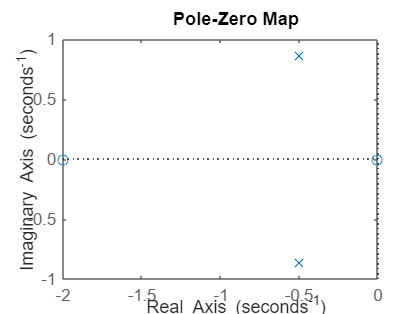

pzmap(H);

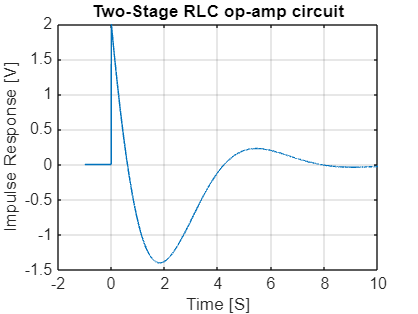

% Impulse Response
[R,P,K] = residue(num, dem);
% h(t) = K + R(1)*exp(P(1)*t) + R(2)*exp(P(2)*t);
t = linspace(-1,10, 1e4);
h = R(1)*exp(P(1)*t) + R(2)*exp(P(2)*t);
h = h.*(t>=0);
figure;
plot(t,h)
xlabel('Time [S]')
ylabel('Impulse Response [V]')
grid on;
title('Two-Stage RLC op-amp circuit')

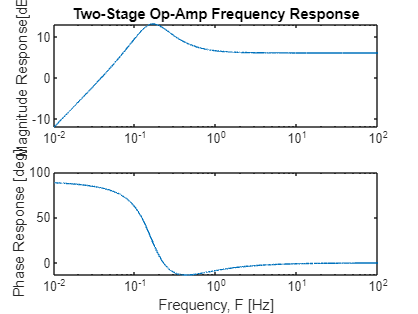

% Bode Plots
% H(w) = H(s=jw)
f = logspace(-2,2,1e4);
s = j * f*2*pi;
FreqResp = (num(1)*(s.^2)+num(2).*s+num(3))./...
    (dem(1)*(s.^2)+dem(2).*s+dem(3));
mag = abs(FreqResp);
phase = angle(FreqResp)*180/pi;
figure; 
subplot(2,1,1)
    semilogx(f,20*log10(mag));
    ylabel('Magnitude Response[dB]')
    title('Two-Stage Op-Amp Frequency Response')
subplot(2,1,2)
    semilogx(f,phase);
    ylabel('Phase Response [deg]')
    xlabel('Frequency, F [Hz]')